coef = 0.5; % unit distance between sensors divided by the wavelength of the signal

input = [0 3 3];        % [nested_array M1 M2]
% input = [1 2 3];      % [coprime_array M1 M2]
% input = [2 4 3];      % [super_nested_array M1 M2]
% input = [3 4 4 3];    % [augmented_nested_array_1 M1 M2 L1]
% input = [4 7 4];      % [augmented_nested_array_2 M1 M2]

if input(1) ~= 1
    M = sum(input(2:3))                                     % # of sensors
else
    M = 2 * input(2) - 1 + input(3)
end

M = 6

sensor_locations = Sensor_Locations(input)                  % sensor locations

sensor_locations =      1     2     3     4     8    12


sensor_placement = Sensor_Placement(sensor_locations)       % sensor places (in order to visualize the array)

sensor_placement =      1     1     1     1     0     0     0     1     0     0     0     1


diff_coarray = Diff_Coarray(sensor_placement)               % difference coarray

diff_coarray =      1     1     1     1     1     1     1     2     1     2     3     6     3     2     1     2     1     1     1     1     1     1     1


uDOF = Uniform_Degrees_Of_Freedom(diff_coarray)             % uniform degrees of freedom

uDOF = 23

LuDOF = One_Side_Uniform_Degrees_Of_Freedom(diff_coarray)   % one side uniform degrees of freedom

LuDOF = 11

Now, let's use the calculated sensor_locations to compute the array pattern

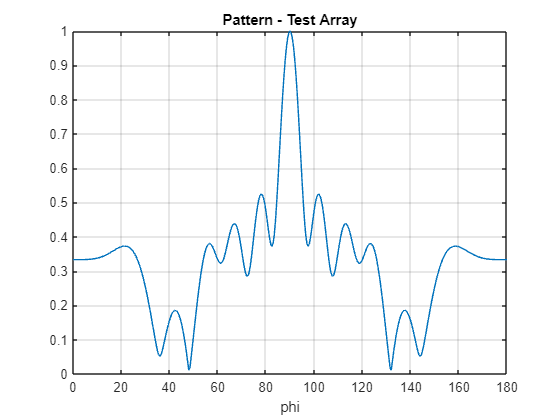

Array_Pattern(sensor_locations, coef)

and solve an example DOA problem

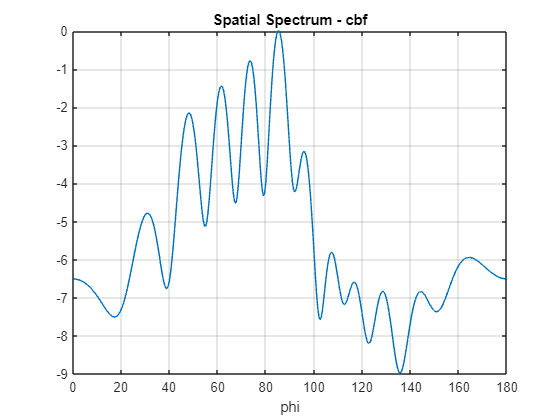

% doa = sort(randi(179, 1, 2));
% doa = [50 150];
doa = 90 - asind(0:0.2:0.6) - 5;                            % source angles
snapshots = 1000;                                           % # of snapshots
SNR_dB = 0;                                                 % signal to noise ratio in decibels
C = Mutual_Coupling(100, 0.1, M, sensor_locations);         % mutual coupling

Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "cbf", C);

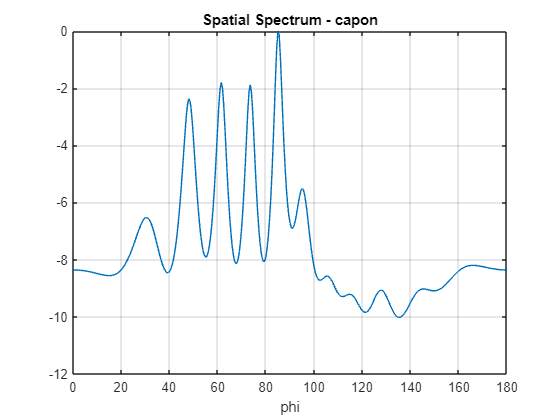

Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "capon", C);

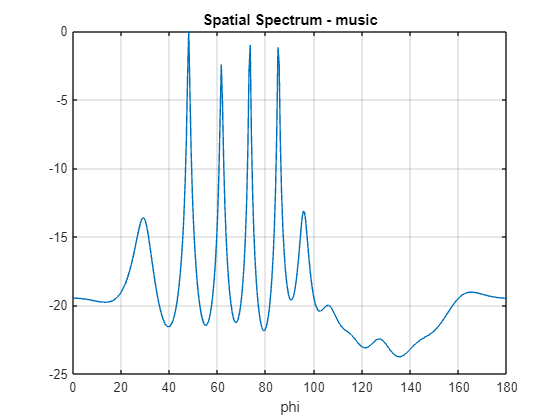

Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "music", C);

#### Testing Area

Spatial Smoothing is tried here but not achieved yet.

n = length(doa);
N = 1000;
SNR = 0;
M_v = sensor_locations(end);

s = zeros(n, N);
theta = 180 * rand(n, 1);
for i = 1:n
    s(i, :) = exp(1i * 2 * pi * coef * (0:N-1) * cosd(theta(i)));
end
v = (1 / 10^(SNR/10)) * (1/sqrt(2)) * (randn(M, N) + 1i * randn(M, N));

A = zeros(M, n);
for i = 1:n
    A(:, i) = exp(1i * 2 * pi * coef * sensor_locations.' * cosd(doa(i)));
end

y = C * A * s + v;
Ry = (1 / N) * (y * y');
z = Ry(:);

A_d = khatri_rao(conj(A), A);
p = zeros(n, 1);
for i = 1:n
    p(i) = var(s(i, :));
end

one_v = eye(M); one_v = one_v(:);
sigma_v = 0;
for i = 1:M
    sigma_v = sigma_v + (1 / M) * var(v(i, :));
end

z_ = A_d * p + sigma_v * one_v;

A1 = Sort_According_to_Sensor_Locations(Discard_Repeating_Rows(A_d));
e = zeros(2 * M_v - 1, 1); e(M_v) = 1;

z1 = A1 * p + sigma_v * e;
R_z1 = zeros(M_v);
for i = 1:M_v
    z1_i = z1(i:i + M_v - 1);
    R_z1 = R_z1 + (1 / M_v) * (z1_i * z1_i');
end
R_z1

R_z1 =    6.1920 + 0.0000i   0.7572 - 3.3713i  -1.0715 + 0.2684i   1.1514 + 0.0424i  -1.1354 - 1.6650i  -3.1371 + 2.1453i   1.1164 + 0.3566i  -2.3595 - 2.5292i  -2.7617 + 2.2135i   1.2640 + 1.4292i   0.6343 - 2.9442i  -0.9359 + 0.6329i
   0.7572 + 3.3713i   6.9799 + 0.0000i   0.8735 - 3.7807i  -0.9552 + 0.3899i   1.3649 - 0.0673i  -1.6982 - 2.2899i  -2.9478 + 2.1959i   1.5030 - 0.4803i  -2.5969 - 2.6997i  -2.7860 + 2.1387i   1.9718 + 1.3169i   0.6343 - 2.9442i
  -1.0715 - 0.2684i   0.8735 + 3.7807i   6.5580 + 0.0000i   0.8387 - 3.7729i  -0.6776 + 0.2976i   1.1399 - 1.1486i  -1.8594 - 2.1116i  -2.0395 + 1.6317i   1.3491 - 0.6970i  -2.6489 - 2.5977i  -2.7860 + 2.1387i   1.2640 + 1.4292i
   1.1514 - 0.0424i  -0.9552 - 0.3899i   0.8387 + 3.7729i   6.5860 + 0.0000i   0.8299 - 3.8393i  -0.9245 + 0.3546i   1.1863 - 1.1539i  -2.0079 - 2.3289i  -2.1046 + 1.6668i   1.3491 - 0.6970i  -2.5969 - 2.6997i  -2.7617 + 2.2135i
  -1.1354 + 1.6650i   1.3649 + 0.0673i  -0.6776 - 0.2976i   0.8299 + 3.8393i 

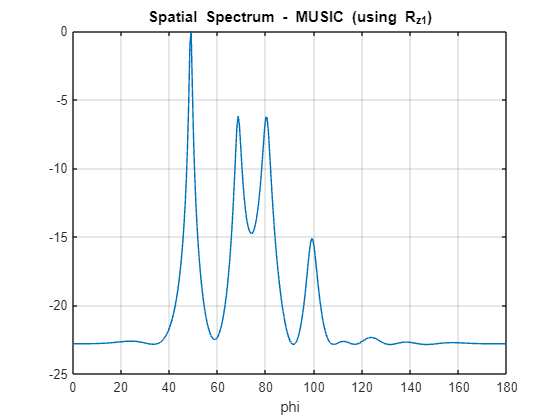

MUSIC(M, n, coef, R_z1);

doa

doa =    85.0000   73.4630   61.4218   48.1301


### Functions Related To DOA Estimation

#### Array Pattern Computation

function Array_Pattern(sensor_locations, coef)

angles = 0:0.5:180;
pattern = zeros(1, length(angles));
for i = 1:length(angles)
    h = exp(1i * 2 * pi * coef * sensor_locations.' * cosd(angles(i)));
    pattern(i) = abs(sum(h));
end
pattern = pattern / max(pattern);

figure;
plot(angles, pattern);
xlabel('phi'); xlim([0 180]);
title('Pattern - Test Array');
grid on;
end

#### Spatial Spectrum Computation

function spatial_spectrum = Spatial_Spectrum(M, sensor_locations, doa, N, SNR, coef, method, C)
n = length(doa);

s = zeros(n, N);
theta = 180 * rand(n, 1);
for i = 1:n
    s(i, :) = exp(1i * 2 * pi * coef * (0:N-1) * cosd(theta(i)));
end
v = (1 / 10^(SNR/10)) * (1/sqrt(2)) * (randn(M, N) + 1i * randn(M, N));

A = zeros(M, n);
for i = 1:n
    A(:, i) = exp(1i * 2 * pi * coef * (sensor_locations - 1).' * cosd(doa(i)));
end

y = C * A * s + v;

angles = 0:0.5:180;
spatial_spectrum = zeros(1, length(angles));

if method == "cbf"
    for i = 1:length(angles)
        h = exp(1i * 2 * pi * coef * (sensor_locations - 1).' * cosd(angles(i)));
        spatial_spectrum(i) = abs(h' * (y * y') * h);
    end
else
    Ry = (1 / N) * (y * y');

    if method == "capon"
        for i = 1:length(angles)
            a_ = exp(1i * 2 * pi * coef * (sensor_locations - 1).' * cosd(angles(i)));
            h = ((eye(M)/(Ry)) * a_) / (a_' * (eye(M)/(Ry)) * a_);
            spatial_spectrum(i) = abs(h' * (y * y') * h);
        end

    else % method == "music"
        [eig_vecs, ~] = eig(Ry);    % eigen decomposition of the covariance matrix
        G = eig_vecs(:, 1:M-n);     % noise space
        
        for i = 1:length(angles)
            a_ = exp(1i * 2 * pi * coef * (sensor_locations - 1).' * cos(angles(i) * pi / 180));
            spatial_spectrum(i) = 1/abs(a_' * (G * G') * a_);
        end
    end
end

spatial_spectrum = spatial_spectrum / max(spatial_spectrum);

figure;
plot(angles, 10 * log10(spatial_spectrum));
xlabel('phi'); xlim([0 180]);
title_str = 'Spatial Spectrum - ' + method;
title(title_str);
grid on;
end

#### MUSIC

This function works for a given covariance matrix. I try to use it when I calculate a covariance matrix using spatial smoothing.

function spatial_spectrum = MUSIC(M, n, coef, Rz1)
angles = 0:0.5:180;
spatial_spectrum = zeros(1, length(angles));

M_v = length(Rz1(:, 1));

[eig_vecs, ~] = eig(Rz1);    % eigen decomposition of the covariance matrix
G = eig_vecs(:, 1:M_v-n);     % noise space

for i = 1:length(angles)
    a_ = exp(1i * 2 * pi * coef * (0:M_v-1).' * cosd(angles(i)));
    spatial_spectrum(i) = 1/abs(a_' * (G * G') * a_);
end
spatial_spectrum = spatial_spectrum / max(spatial_spectrum);

figure;
plot(angles, 10 * log10(spatial_spectrum));
xlabel('phi'); xlim([0 180]);
title_str = 'Spatial Spectrum - MUSIC (using R_{z1})';
title(title_str);
grid on;
end

#### Sensor Locations

function sensor_locations = Sensor_Locations(input)
if input(1) == 0 % nested array
    sensor_locations = Nested_Array_Locations(input(2:end));

elseif input(1) == 1 % coprime array
    sensor_locations = Coprime_Array_Locations(input(2), input(3));

elseif input(1) == 2 % super-nested array
    sensor_locations = Super_Nested_Array_Locations(input(2), input(3));
elseif input(1) == 3 % augmented-nested array 1
    sensor_locations = Augmented_Nested_Array_1_Locations(input(2), input(3), input(4));
elseif input(1) == 4 % augmented-nested array 2
    sensor_locations = Augmented_Nested_Array_2_Locations(input(2), input(3));
end
end

#### Nested Array Locations

function sensor_locations = Nested_Array_Locations(N)
K = length(N); % number of levels

sensor_locations = zeros(1, sum(N));
sensor_locations(1:N(1)) = 1:N(1);
for i = 2:K
    locations = 1:N(i);
    for j = 1:i-1
        for n = 1:N(i)
            locations(n) = locations(n) * (N(j) + 1);
        end
    end
    idx_init = sum(N(1:i-1))+1;
    idx_end = idx_init + N(i) - 1;
    sensor_locations(idx_init:idx_end) = locations;
end
end

#### Coprime Array Locations

function sensor_locations = Coprime_Array_Locations(M, N)
sensor_locations_1 = 1 + M * (0:N-1);
sensor_locations_2 = 1 + N * (0:2*M-1);

sensor_locations = sort([sensor_locations_1 sensor_locations_2(2:end)]);
end

#### Super-Nested Array Locations

function sensor_locations = Super_Nested_Array_Locations(N1, N2)
REM = rem(N1, 4);
r = floor(N1 / 4);
if REM == 0
    A1 = r; B1 = r - 1; A2 = r - 1; B2 = r - 2;
elseif REM == 1
    A1 = r; B1 = r - 1; A2 = r - 1; B2 = r - 1;
elseif REM == 2
    A1 = r + 1; B1 = r - 1; A2 = r; B2 = r - 2;
elseif REM == 3
    A1 = r; B1 = r; A2 = r; B2 = r - 1;
end
X1 = 1 + 2 * (0:A1);
Y1 = N1 + 1 - (1 + 2 * (0:B1));
X2 = (N1 + 1) + (2 + 2 * (0:A2));
Y2 = 2 * (N1 + 1) - (2 + 2 * (0:B2));
Z1 = (2:N2) * (N1 + 1);
Z2 = N2 * (N1 + 1) - 1;

sensor_locations = sort([X1 Y1 X2 Y2 Z1 Z2]);
end

#### Augmented Nested Array 1 Positions

function sensor_locations = Augmented_Nested_Array_1_Locations(N1, N2, L1)
if L1 == -1
    L1 = ceil(0.5 * (N1 + 1));
end
temp_locations = Nested_Array_Locations([N1 N2]); % parent nested array
temp_locations(N1 - L1 + 1:N1) = (N1 + 1) * N2 + temp_locations(N1 - L1 + 1:N1) - temp_locations(N1 - L1 + 1) + 1;
sensor_locations = sort(temp_locations);
end

#### Augmented Nested Array 2 Positions

function sensor_locations = Augmented_Nested_Array_2_Locations(N1, N2)
temp_locations = Nested_Array_Locations([N1 N2]); % parent nested array
temp_locations(3:2:N1) = (N1 + 1) * N2 - (rem(N1, 2) + 1) + temp_locations(3:2:N1);
sensor_locations = sort(temp_locations);
end

#### Sensor Placement

function sensor_placement = Sensor_Placement(sensor_locations)
sensor_placement = zeros(1, sensor_locations(end));
sensor_placement(sensor_locations) = 1;
end

#### Difference Coarray

function diff_coarray = Diff_Coarray(sensor_placement)
N = length(sensor_placement);
diff_coarray = zeros(1, 2 * N - 1);
for i = 1:N
    diff_coarray(N + i - 1) = sensor_placement(i:end) * sensor_placement(1:end-i+1).';
end
diff_coarray(1:N-1) = diff_coarray(end:-1:N+1);
end

#### Degrees of Freedom

function degrees_of_freedom = Degrees_Of_Freedom(N)
K = length(N); % number of levels
degrees_of_freedom = 2 * (([0 N] * [N 0].') + N(K) - 1) + 1;
end

#### Uniform Degrees of Freedom

function uniform_degrees_of_freedom = Uniform_Degrees_Of_Freedom(diff_coarray)
uniform_degrees_of_freedom = 0;
length_diff_coarray = length(diff_coarray);
for i = (length_diff_coarray + 1)/2:length_diff_coarray
    if diff_coarray(i) == 0
        break
    end
    uniform_degrees_of_freedom = uniform_degrees_of_freedom + 1;
end
uniform_degrees_of_freedom = 2 * uniform_degrees_of_freedom - 1;
end

#### One-Side Uniform Degrees of Freedom

function one_side_uniform_degrees_of_freedom = One_Side_Uniform_Degrees_Of_Freedom(diff_coarray)
uniform_degrees_of_freedom = Uniform_Degrees_Of_Freedom(diff_coarray);
one_side_uniform_degrees_of_freedom = 0.5 * (uniform_degrees_of_freedom - 1);
end

#### Mutual Coupling

function C = Mutual_Coupling(B, c_s, M, sensor_locations)
C = eye(M);

if B < 1 % if mutual_coupling does not exist
    return
end

c = zeros(B-1, 1);
c(1) = c_s * exp(1i * pi / 3);
c(2:B-1) = c(1) * exp(-1i * pi * (1:B-2).' / 8);
for i = 1:M-1
    for j = i+1:M
        lag = abs(sensor_locations(i) - sensor_locations(j));
        if lag <= B
            C(i, j) = c(lag);
            C(j, i) = c(lag);
        end
    end
end
end

### Functions Used In Spatial Smoothing

#### Khatri-Rao Product

function X = khatri_rao(A1, A2)
[r1, c] = size(A1);
[r2, ~] = size(A2);
X = zeros(r1*r2, c);
for j = 1:c
    for i = 1:r1
        row_init = (i-1) * r2 + 1;
        row_end = i * r2;
        X(row_init:row_end, j) = A1(i, j) * A2(:, j);
    end
end
end

#### Discard Repeating Rows

function X2 = Discard_Repeating_Rows(X1)
X2 = X1(1, :);
for i = 2:length(X1(:, 1))
    temp_X = X2 - ones(length(X2(:, 1)), 1) * X1(i, :);
    exists = false;
    for j = 1:length(X2(:, 1))
        if round(norm(temp_X(j, :))) == 0
            exists = true;
            break
        end
    end
    if ~exists
        X2 = [X2; X1(i, :)];
    end
end
end

#### Sort According to Sensor Locations In The Difference Coarray

function X2 = Sort_According_to_Sensor_Locations(X1)
[M, N] = size(X1);
X2 = zeros(M, N);
middle_idx = 0.5 * (M+1);
X2(middle_idx, :) = X1(1, :);
X1 = X1(2:end, :);
for i = 1:0.5 * (M-1)
    X2(middle_idx + i, :) = X1(i, :);
    X2(middle_idx - i, :) = conj(X1(i, :));

    X1(1, :) = conj(X1(1, :));
    X1 = Discard_Repeating_Rows(X1);
end
end